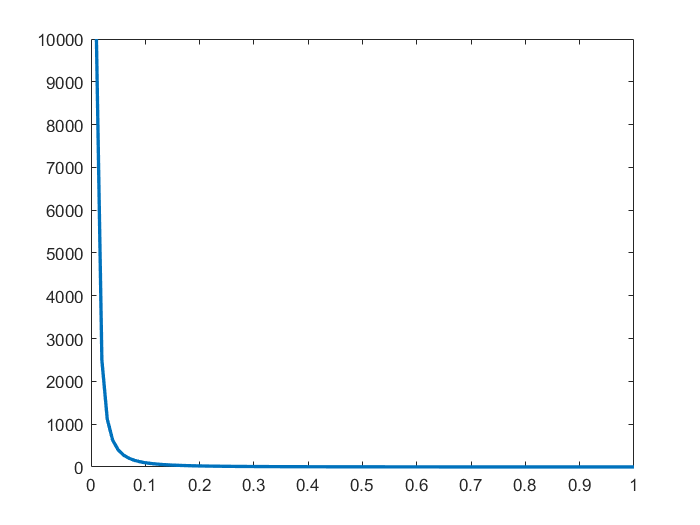

clear;
func = @(r,a,s)(r.^-2);
r = 0:0.01:1;
a = 1;
s = -0.5;
plot(r, func(r,a,s),'linewidth', 2);

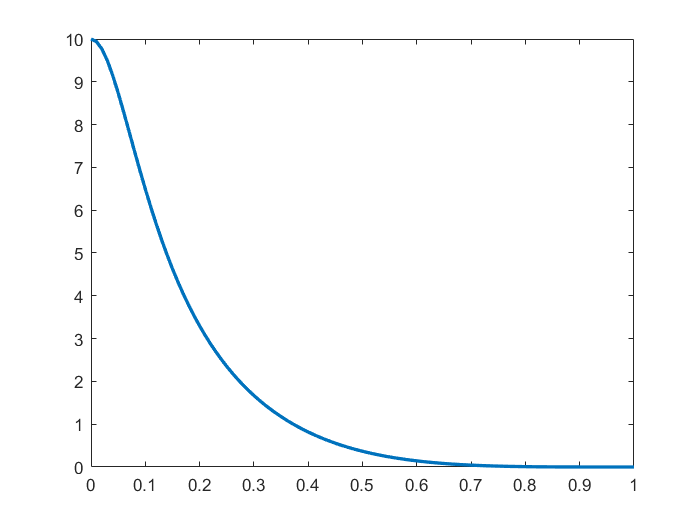

clear;
func = @(r,a,s)(1-r).^4.*(4*r+1).*((a+r.^2).^s);
r = 0:0.01:1;
a = 0.01;
s = -0.5;
f = func(r,a,s);
plot(r, func(r,a,s),'linewidth', 2);

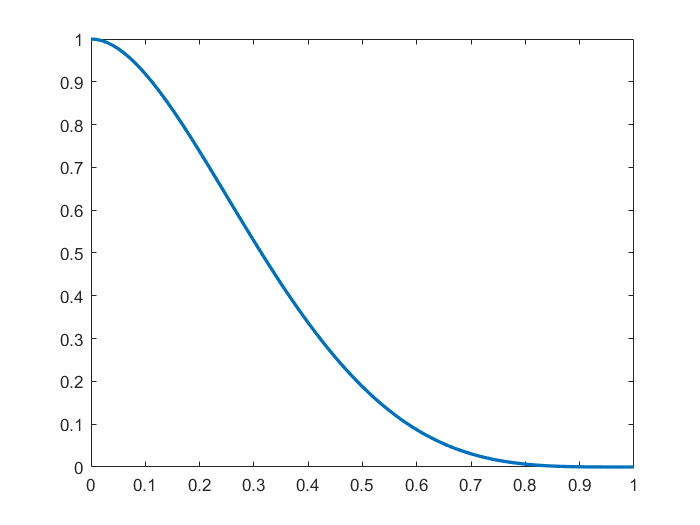

clear;
func = @(r,a,s)(((1-r).^4).*(4*r+1));
r = 0:0.01:1;
a = 0;
s = -0.5;
plot(r, func(r,a,s),'linewidth', 2);

% 生成插值点集
X = -1:0.1:1;
F = zeros(1,length(X));

for i=1:length(X)
    F(i) = 1/(1+25*X(i)*X(i));
    %F(i) = abs(X(i))+X(i)/2-X(i)*X(i);
end

% 生成拟合点集
step = 0.01;
x = -1:step:1;
f = zeros(1,length(x));

for i=1:length(x)
    f(i) = 1/(1+25*x(i)*x(i));
    %f(i) = abs(x(i))+x(i)/2-x(i)*x(i);
end

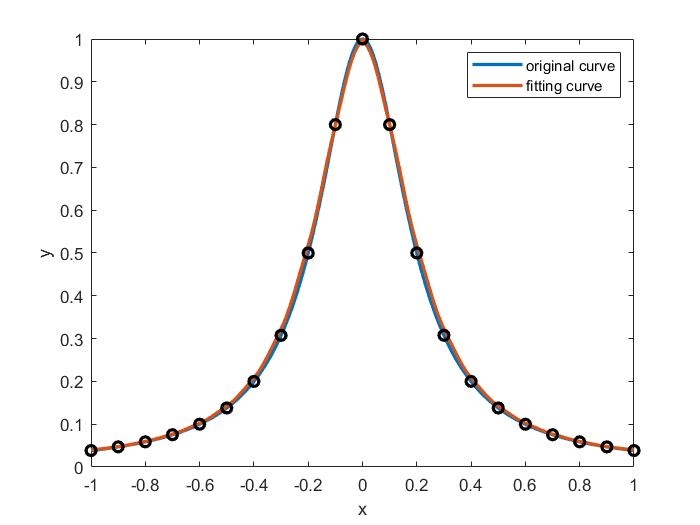

%%% Our method
r = zeros(1,length(X));
P = zeros(1,length(x));
a = 0.2*ones(1,length(X));
a(11) = 0;
s = -0.5;
rhoi=0.25;

% err = zeros(1,length(X));
% for j = 1:length(X)
%     for i = 1: length(X)
%         if i==j
%             continue
%         end
%         if abs(X(j)-X(i)) > rhoi
%             continue
%         end
%         err(j) = err(j) + abs(F(j)-F(i));
%     end
% end
% 
% maxerr = max(err);
% minerr = min(err);
% a = 1*(1-(err-minerr)./(maxerr-minerr));
% plot(X,a);

% maxa=1;
% mina=0.5;
% for i=1:length(X)
%         a(i) = maxa -(maxa - mina) ...
%             *(err(i) - minerr) / (maxerr - minerr);
% end
% a(11)=0;

for j = 1:length(x)
    phi = zeros(1,length(X));
    for i = 1: length(X)
        if a(i)<1e-7 && abs(x(j)-X(i))<1e-7
            phi = zeros(1,length(X));
            phi(i) = 1;
            break;
        end
        r(i) = abs(x(j)-X(i))./rhoi;
        if r(i)>1
            phi(i) = 0;
            continue
        end
        phi(i) = ((1-r(i)).^4)*(4*r(i)+1)*((a(i)+(r(i).^2)).^s);

    end
    P(j) = (F*phi')/sum(phi);
end

r = zeros(1,length(X));
P0 = zeros(1,length(X));
for j = 1:length(X)
    phi = zeros(1,length(X));
    for i = 1: length(X)
        if a(i)<1e-7 && abs(X(j)-X(i))<1e-7
            phi = zeros(1,length(X));
            phi(i) = 1;
            break;
        end
        r(i) = abs(X(j)-X(i))./rhoi;
        if r(i)>1
            phi(i) = 0;
            continue
        end
        phi(i) = ((1-r(i)).^4)*(4*r(i)+1)*((a(i)+(r(i).^2)).^s);

    end
    P0(j) = (F*phi')/sum(phi);
end
plot(x,f,x,P, 'linewidth', 2);
hold on;
scatter(X,F,'ok', 'linewidth', 2);
legend('original curve','fitting curve')
xlabel('x');ylabel('y');
hold off;

disp(max(abs(f-P)))

    0.0236



disp(mean(abs(f-P)))

    0.0066



disp(max(abs(F-P0)))

    0.0185



disp(mean(abs(F-P0)))

    0.0051



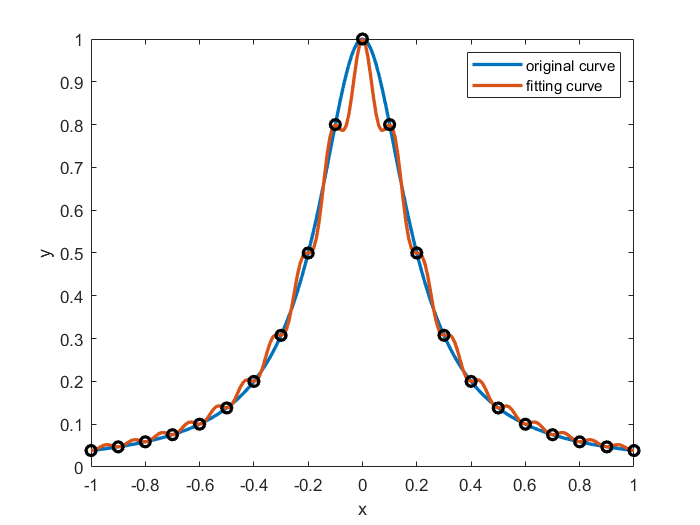

%Shepard's method
u = -2;
%%%计算测试数据点的函数值
r = zeros(1,length(X));
P = zeros(1,length(x));
for j = 1:length(x)
    phi = zeros(1,length(X));
    for i = 1: length(X)
        rhoi=0.25;
        if abs(x(j)-X(i))<1e-7
            phi = zeros(1,length(X));
            phi(i) = 1;
            break;
        end
        r(i) = abs(x(j)-X(i))./rhoi;
        % if r(i)>1
        %     continue
        % end
        phi(i) = r(i).^u;
    end
    P(j) = (F*phi')/sum(phi);
end

%%%计算插值数据点的函数值
r = zeros(1,length(X));
P0=zeros(1,length(X));
for j = 1:length(X)
    phi = zeros(1,length(X));
    for i = 1: length(X)
        rhoi=0.25;
        if abs(X(j)-X(i))<1e-7
            phi = zeros(1,length(X));
            phi(i) = 1;
            break;
        end
        r(i) = abs(X(j)-X(i))./rhoi;
        % if r(i)>1
        %     continue
        % end
        phi(i) = r(i).^u;
    end
    P0(j) = (F*phi')/sum(phi);
end
plot(x,f,x,P, 'linewidth', 2);
hold on;
scatter(X,F,'ok', 'linewidth', 2);
legend('original curve','fitting curve')
xlabel('x');ylabel('y');
hold off;

disp(max(abs(f-P)))

    0.1201



disp(mean(abs(f-P)))

    0.0172



disp(max(abs(F-P0)))

     0



disp(mean(abs(F-P0)))

     0



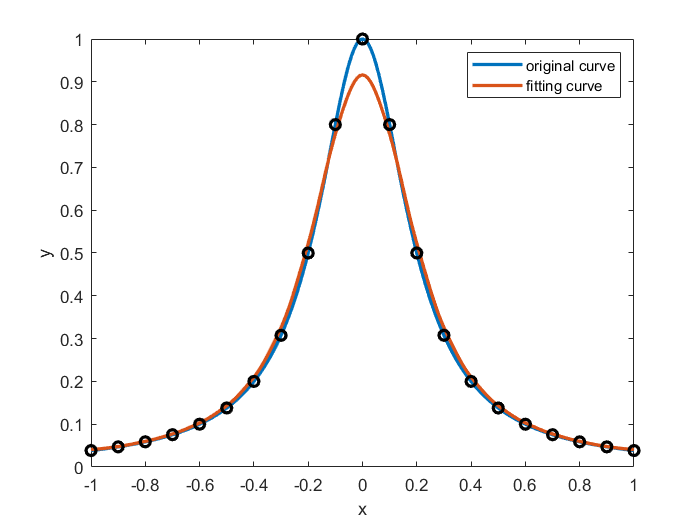

%%%Wendland's method
%%%计算测试数据点的函数值
phi = zeros(1,length(X));
r = zeros(1,length(X));
P = zeros(1,length(x));
for j = 1: length(x)
    for i = 1: length(X)
        rhoi=0.25;
        r(i) = abs(x(j)-X(i))./rhoi;
        if r(i)>1
            continue
        end
        phi(i) = (1-r(i))^4 * (4*r(i)+1);
    end
    P(j) = (F*phi')/sum(phi);
end
%%%计算插值数据点的函数值
r = zeros(1,length(X));
P0=zeros(1,length(X));
for j = 1:length(X)
    phi = zeros(1,length(X));
    for i = 1: length(X)
        rhoi=0.25;
        r(i) = abs(X(j)-X(i))./rhoi;
        if r(i)>1
            continue
        end
        phi(i) = (1-r(i))^4 * (4*r(i)+1);
    end
    P0(j) = (F*phi')/sum(phi);
end

plot(x,f,x,P, 'linewidth', 2);
hold on;
scatter(X,F,'ok','linewidth', 2);
legend('original curve','fitting curve')
xlabel('x');ylabel('y');
hold off;

disp(max(abs(f-P)))

    0.0839



disp(mean(abs(f-P)))

    0.0129



disp(max(abs(F-P0)))

    0.0839



disp(mean(abs(F-P0)))

    0.0122

